# Matlab Data Analysis Tutorial: Analysis of Galaxy Clusters from the Sloane Digital Sky Survey

## Introduction

Matlab provides an excellent suite of tools for rapidly constructing applications which you can use to prepare and process data. In this live script we explore use the following matlab tools to explore a data set gathered from the Sloane digital sky survey.   

- [Scatter plots](https://uk.mathworks.com/help/matlab/ref/scatter.html?searchHighlight=scatter%20plot&s_tid=doc_srchtitle)

- [Histogram bin counts](https://uk.mathworks.com/help/matlab/ref/histcounts.html?searchHighlight=histcounts&s_tid=doc_srchtitle)

- [Interactive controls for live scripts](https://uk.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html?searchHighlight=live%20script%20control&s_tid=doc_srchtitle)

- [k-means clustering](https://uk.mathworks.com/help/stats/kmeans.html?searchHighlight=kmeans&s_tid=doc_srchtitle)

## Overview

The Sloane digital sky survey (SDSS) is a collection of data gathered by ground based robotic telescopes and spectroscopes. This is used by citizen science experiments such as [galaxyzoo](https://www.zooniverse.org/projects/zookeeper/galaxy-zoo/) to investigate the many galaxies which have been revealed by this robotic survey.

Since the data is public it means we can easily download data using services provided by SDSS

Here we use k-means cluster analysis as a classification method for our collection of galaxies and as a tool for investigating the distribution and characteristics of this collection.

Our initial analysis starts with the classification of galaxies located near well known star clusters e.g.

NGC 2419, Pal 3, Pal 4, NGC 4147, NGC 5024, M53, NGC 5053, NGC 5272, M3, NGC 5466, Pal 5, NGC 5904, M5, Pal 14, NGC 6205, M13, NGC 6341, M92

With further analysis we can run the analysis with a collection of galaxies from a distribution of well known galactic clusters for example

[https://en.wikipedia.org/wiki/List_of_galaxy_groups_and_clusters](https://en.wikipedia.org/wiki/List_of_galaxy_groups_and_clusters)

- Abell 1656

- Copeland Septet

- NGC 7331             Deer Lick Group

- Leo Triplet

- NGC 4477             Markarians Chain  

- NGC 6027             Seyferts Sextet

- HCG 92                 Stephans Quintet

- Virgo Cluster

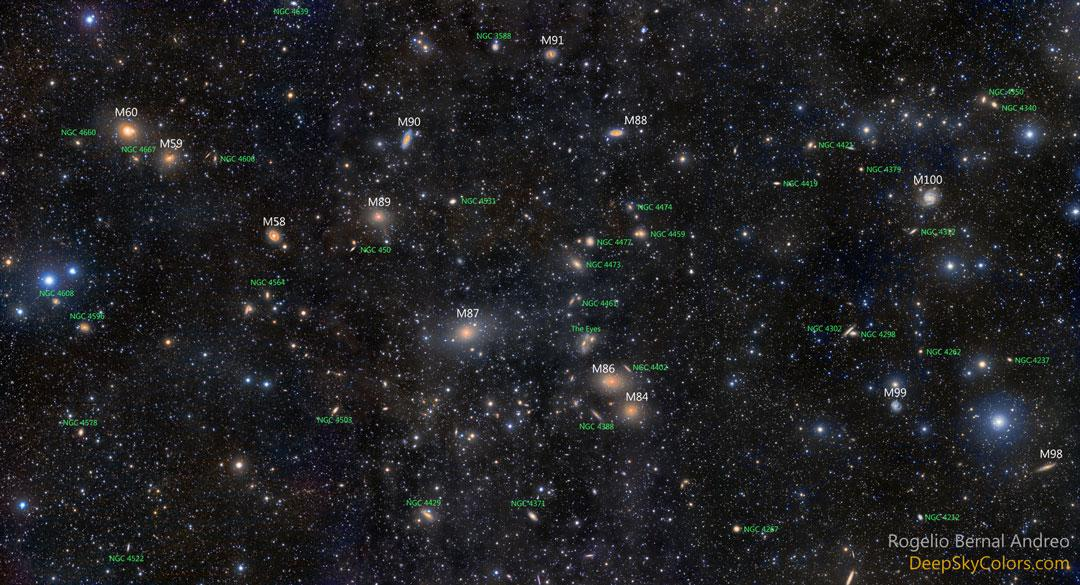

An image of the Virgo super cluster from [Astronomy picture of the day](https://apod.nasa.gov/apod/ap150804.html), this is one of the largest galaxy clusters.

## Loading the Data

The galaxy data is contained in a CSV file, we used the [matlab import data tool](https://uk.mathworks.com/help/matlab/ref/importtool-app.html) to generate a script to load the data. The script has lines to omit invalid data.

%% Initialize variables.
%filename = 'all.csv'; % uncomment this to load data for galaxies near globular clusters
filename = 'all-galaxclusters.csv'; %uncomment this to load data for the list of galaxy clusters

galaxyload %load script generated by the matlab import tool


The data is returned in a matlab [table](https://uk.mathworks.com/help/matlab/ref/table.html?searchHighlight=table&s_tid=doc_srchtitle) data type

## Using Scatter Plots to View  the Galaxy Collection

Generate cartesian coordinates using the right acension and declination. Galactic redshift is used as a proxy for radial distance.

x=all1.redshift.*sin(all1.ra).*cos(all1.dec);
y=all1.redshift.*sin(all1.ra).*sin(all1.dec);
z=all1.redshift.*cos(all1.ra);


scatter3(x,y,z);
hold on


Plot the centre of the model as a redpoint

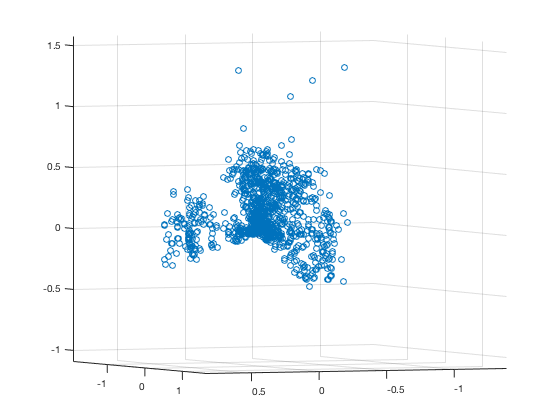

plot3(0,0,0,'r*');
hold off

Use the zoom, pan  and orientation control in the graphics window to explore different clusters. Although the algorithm has selected some galaxies with very high redshift, can you identify distinct clusters in the distribution.

## How many galaxies are observed for different redshifts?

To answer this question we use the histcounts function which returns the number of data points in each bin along with the edge positions of each bin. This is a proxy for a distribution known as a radial distribution function. The use of [radial distrbution functions](https://en.wikipedia.org/wiki/Radial_distribution_function) enables the investigation of possible correllations between the objects in our distributions.

We use the histcounts function which returns the number of objects in each bin along with the edge positions for each bin.

numbins=50;
[N,edges]=histcounts(all1.redshift,numbins);


Use the bar function to display the data as a bar chart.

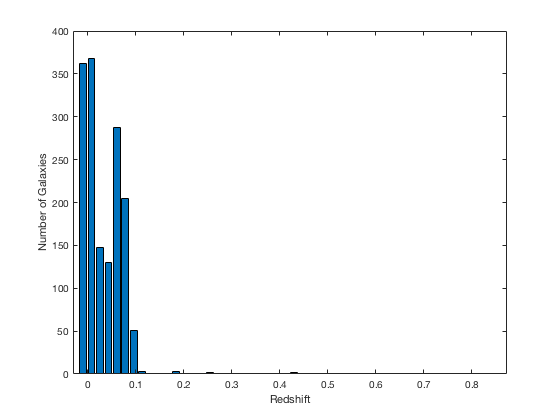

bar(edges(1:50),N);
xlabel('Redshift')
ylabel('Number of Galaxies')

We can see that most of the galaxies have a redshift less than 1.0. To see how these  are distributed in more detail we use a conditional statement to pick out all the galaxies with redshift less than 1 as shown below.

sel=all1(all1.redshift<1.0,:); %Note the additional colon


Having filtered and selected the data we require we replot the distribution

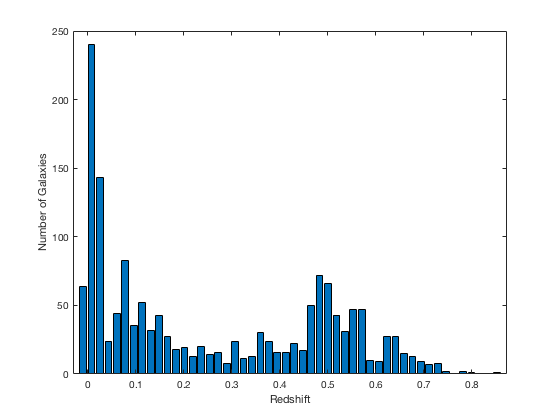

[Nsel,edges]=histcounts(sel.redshift,numbins);
bar(edges(1:50),Nsel)
xlabel('Redshift')
ylabel('Number of Galaxies')

We can see clearly from the initial scatter plot that most of the galaxies are located at redshift 0.03 and 0.1, there is a second peak around redshift 0.5. It would be interesting to how galaxies with redshift greater than 0.7 are distributed.

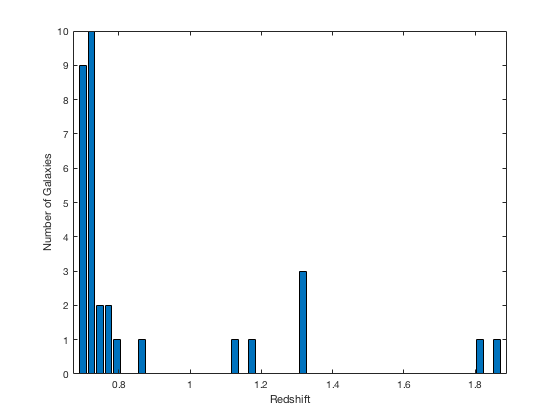


sel=all1(all1.redshift>0.7 & all1.redshift<2.0,:);
[Nsel,edges]=histcounts(sel.redshift,numbins);
bar(edges(1:50),Nsel)
xlabel('Redshift')
ylabel('Number of Galaxies')

## Interactive  Scatter Plot for the Galaxy Distribution

By making use a data filter  and by employing interactive controls Show the Distribution of galaxies for a given redshift range

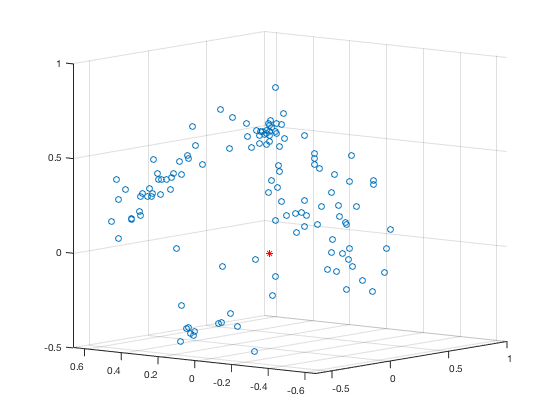

uppershift=1; %default 0.7
lowershift=0.6; %default 0.3
sel1=all1(all1.redshift>lowershift & all1.redshift<uppershift,:);

x=sel1.redshift.*sin(sel1.ra).*cos(sel1.dec);
y=sel1.redshift.*sin(sel1.ra).*sin(sel1.dec);
z=sel1.redshift.*cos(sel1.ra);

scatter3(x,y,z);
hold on

plot3(0,0,0,'r*');
hold off

## How is this Collection of Galaxies Clustered?

Lets see how galaxies are clustered together

%kmeans cluster
numclus=7;


A = sel1{:,{'ra','dec','u','g','r','i','z','redshift'}};
idx4 = kmeans(A,numclus);


Plot and colour the galaxies according to cluster they belong to

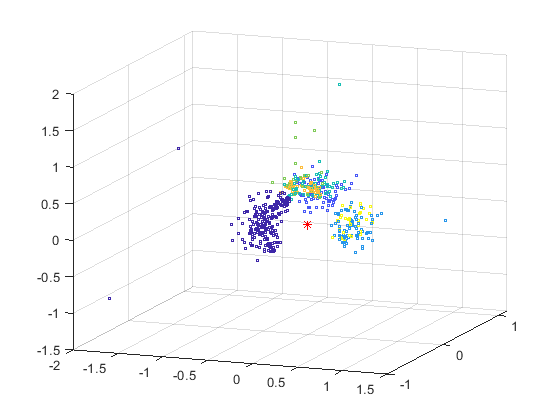

x=sel1.redshift.*sin(sel1.ra).*cos(sel1.dec);
y=sel1.redshift.*sin(sel1.ra).*sin(sel1.dec);
z=sel1.redshift.*cos(sel1.ra);

scatter3(x,y,z,3,idx4);
hold on

plot3(0,0,0,'r*');
hold off

Plot and colour the galaxies according to the magnitude cluster to which the galaxy belongs

A = sel1{:,{'u','g','r','i','z'}};
idxmag4 = kmeans(A,numclus);

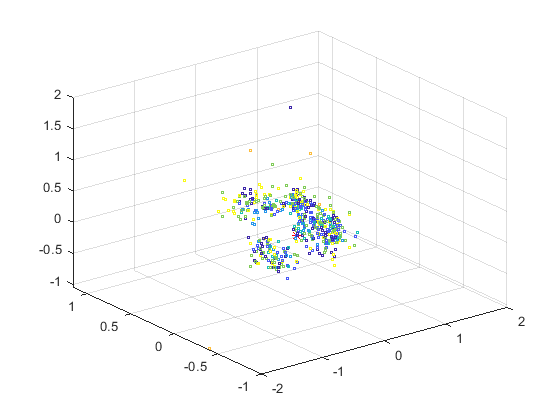

x=sel1.redshift.*sin(sel1.ra).*cos(sel1.dec);
y=sel1.redshift.*sin(sel1.ra).*sin(sel1.dec);
z=sel1.redshift.*cos(sel1.ra);

scatter3(x,y,z,3,idxmag4); %size parameter followed by colour index
hold on

plot3(0,0,0,'r*');
hold off

A = sel1{:,{'ra','dec','redshift'}};
idx4pos = kmeans(A,numclus);

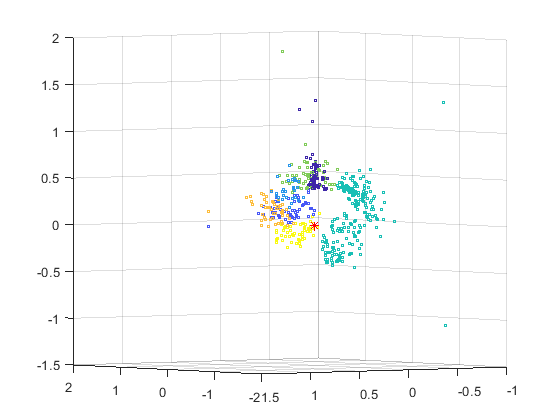



x=sel1.redshift.*sin(sel1.ra).*cos(sel1.dec);
y=sel1.redshift.*sin(sel1.ra).*sin(sel1.dec);
z=sel1.redshift.*cos(sel1.ra);

scatter3(x,y,z,3,idx4pos);
hold on

plot3(0,0,0,'r*');
hold off

Colour the galaxy using the positional clustering.

selectedclusterall=3;%select a cluster from the clustering of all selected galaxies
selectedcluster=4; %select a cluster from the clustering of galaxies by position


Which cluster has the smallest spread of readshift, ra and dec?

numclus

numclus = 7

minalldec=99; %these values used to store
minallra=99;
minalltot=99;
minallred=99;
idallmin=ones(numclus,1);
for i=1:numclus
     selclus=(find(idx4==i));
     selall=sel1(selclus,:);
     numel(selall);

    

    mraall=mean(selall.ra);
    mdecall=mean(selall.dec);
    mredall=mean(selall.redshift);
    
    sz=size(selall);
    difra=0;
    difdec=0;
    difred=0;

    for j=1:sz(1)
        dif=mraall-selall.ra(j);
        difra=difra+dif*dif;
        dif=mdecall-selall.dec(j);
        difdec=difdec+dif*dif;
        dif=mredall-selall.redshift(j);
        difred=difred+dif*dif;
    end
    difallra=difra/sz(1);
    difalldec=difdec/sz(1);
    difallred=difred/sz(1);
    difalltot=difallra+difalldec+difallred;
    
    if (difallra<minallra) && (i~=22) && (i~=33)
        minallra=difallra;
        idallmin(1)=i;
    end
    if (difalldec<minalldec) && (i~=22) && (i~=33)
        minalldec=difalldec;
        idallmin(2)=i;
    end
    if (difallred<minallred) && (i~=22) && (i~=33)
        minallred=difallred;
        idallmin(3)=i;
    end
    if (difalltot<minalltot) && (i~=22) && (i~=33)
        minalltot=difalltot;
        idallmin(4)=i;
    end
    fprintf('All %d %d %g %g %g %g %g %g %g\n',i,sz(1),difallra,difalldec,difallred,difalltot,mraall,mdecall,mredall);
      
%     mindec
%     minra
    

end

All 1 223 0.327425 0.295776 0.0255348 0.648735 187.145 13.1874 0.556508
All 2 80 0.0773851 0.0713237 0.0141185 0.162827 239.848 20.7437 0.57659
All 3 81 0.0801521 0.0518248 0.0142062 0.146183 174.386 21.9247 0.550641
All 4 64 0.0710512 0.0641557 0.0367774 0.171984 169.762 13.1517 0.556482
All 5 37 0.102405 0.0564879 0.0455759 0.204468 195.018 27.9483 0.622065
All 6 45 0.0993018 0.0634939 0.00426628 0.167062 194.902 27.9787 0.531694
All 7 32 0.0603727 0.0677571 0.00335846 0.131488 174.535 21.9652 0.535268


idallmin

idallmin =      7
     3
     7
     7
     1
     1
     1



minallra

minallra = 8.5541e-04

minalldec

minalldec = 0.0361

minallred

minallred = 2.2963e-04

minalltot

minalltot = 0.0767

Now plot a selected cluster one cluster number onlyy

idx4possel=idx4pos

idx4possel =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


selpos=(find(idx4possel~=3));
idx4possel(selpos)=1

idx4possel =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


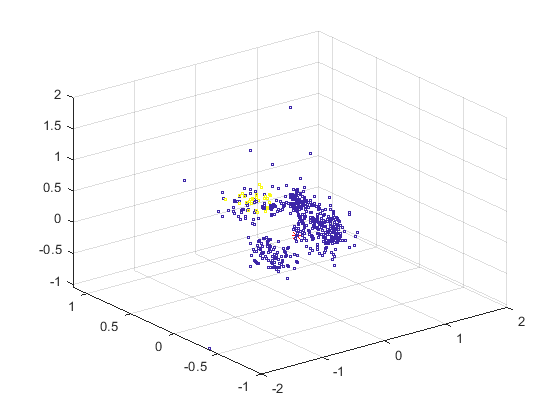



x=sel1.redshift.*sin(sel1.ra).*cos(sel1.dec);
y=sel1.redshift.*sin(sel1.ra).*sin(sel1.dec);
z=sel1.redshift.*cos(sel1.ra);

scatter3(x,y,z,3,idx4possel);
hold on

plot3(0,0,0,'r*');
hold off

A = sel1{:,{'ra','dec','redshift'}};
idx4pos = kmeans(A,numclus);

minposdec=99; %these values used to store
minposra=99;
minpostot=99;
minposred=99;
idposmin=ones(numclus,1);
for i=1:numclus
     selclus=(find(idx4pos==i));
     selpos=sel1(selclus,:);
     numel(selpos);

    

    mrapos=mean(selpos.ra);
    mdecpos=mean(selpos.dec);
    mredpos=mean(selpos.redshift);
    
    sz=size(selpos);
    difra=0;
    difdec=0;
    difred=0;

    for j=1:sz(1)
        dif=mrapos-selpos.ra(j);
        difra=difra+dif*dif;
        dif=mdecpos-selpos.dec(j);
        difdec=difdec+dif*dif;
        dif=mredpos-selpos.redshift(j);
        difred=difred+dif*dif;
    end
    difposra=difra/sz(1);
    difposdec=difdec/sz(1);
    difposred=difred/sz(1);
    difpostot=difposra+difposdec+difposred;
    
    if difposra<minposra && i~=39
        minposra=difposra;
        idposmin(1)=i;
    end
    if difposdec<minposdec && i~=39
        minposdec=difposdec;
        idposmin(2)=i;
    end
    if difposred<minposred && i~=39
        minposred=difposred;
        idposmin(3)=i;
    end
    if difpostot<minpostot && i~=39
        minpostot=difpostot;
        idposmin(4)=i;
    end
    fprintf('All %d %d %g %g %g %g %g %g\n',i,sz(1),difposra,difposdec,difposred,mrapos,mdecpos,mredpos);
%     mindec
%     minra
end

All 1 27 0.0138499 0.026003 0.00319725 182.189 18.5372 0.536457
All 2 38 0.0139794 0.0384137 0.00467494 229.944 2.0774 0.555266
All 3 30 0.0380764 0.0112247 0.00780492 151.38 0.373415 0.572558
All 4 50 0.0143882 0.00926343 0.0104844 198.136 17.8368 0.524652
All 5 42 0.0218152 0.0456259 0.00488669 114.201 38.8759 0.509235
All 6 52 0.00625726 0.024858 0.00734929 249.902 36.4575 0.536619
All 7 29 0.00956002 0.0225404 0.00340478 211.667 28.658 0.530715
All 8 36 0.013865 0.0298195 0.00580241 172.712 28.9905 0.55307
All 9 38 0.0289132 0.0377873 0.0092676 243.037 15.0449 0.549714
All 10 46 0.0160613 0.0132886 0.00110914 205.434 28.7285 0.502964
All 11 18 0.0118469 0.00950056 0.00317561 258.848 42.8175 0.562435
All 12 65 0.0611898 0.0774787 0.00780307 228.979 -0.127891 0.564266
All 13 58 0.025116 0.0125692 0.00309227 198.268 18.4997 0.52676
All 14 30 0.0190006 0.0416203 0.0065433 151.125 -0.0518403 0.558601
All 15 34 0.0170622 0.0347686 0.0069484 250.82 36.2397 0.498803
All 16 31 0.029829 0.01





idposmin

idposmin =      6
    36
    10
    36
     1
     1
     1
     1
     1
     1


minposra

minposra = 0.0063

minposdec

minposdec = 5.1596e-04

minposred

minposred = 0.0011

minpostot

minpostot = 0.0215

selclus=(find(idx4==selectedclusterall));
selall=sel1(selclus,:);
selclus=(find(idx4pos==selectedcluster));
selpos=sel1(selclus,:);

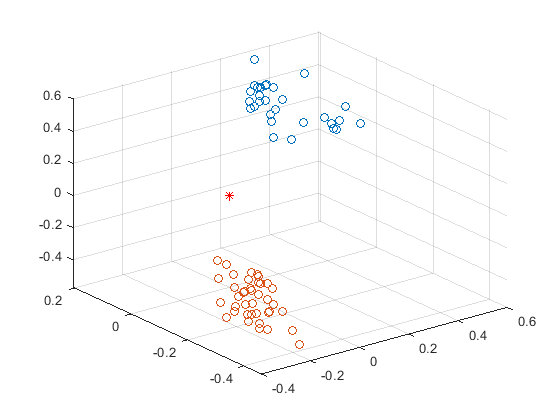

xall=selall.redshift.*sin(selall.ra).*cos(selall.dec);
yall=selall.redshift.*sin(selall.ra).*sin(selall.dec);
zall=selall.redshift.*cos(selall.ra);
[X,Y]=meshgrid(x,y);

hold off;

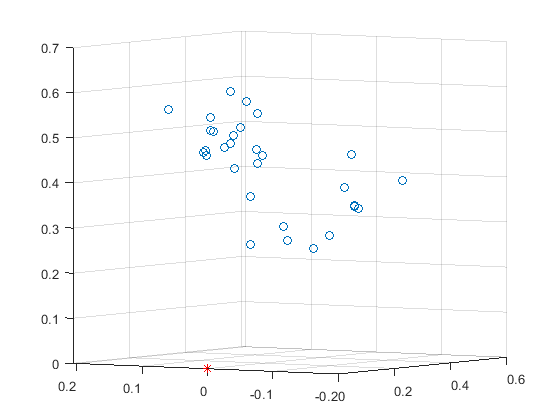

scatter3(xall,yall,zall)
hold on
plot3(0,0,0,'r*')

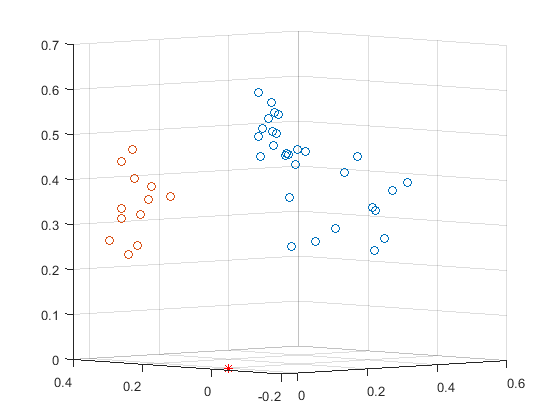

ans = 	1.0e+18 *

    1.2377
    1.2377
    1.2377
    1.2377
    1.2377
    1.2377
    1.2377
    1.2377
    1.2377
    1.2377


xpos=selpos.redshift.*sin(selpos.ra).*cos(selpos.dec);
ypos=selpos.redshift.*sin(selpos.ra).*sin(selpos.dec);
zpos=selpos.redshift.*cos(selpos.ra);
[X,Y]=meshgrid(x,y);
scatter3(xpos,ypos,zpos)
%hold on
plot3(0,0,0,'r*')

selpos.ra

ans =   250.8941
  250.6428
  250.4611
  250.5323
  250.6222
  250.7415
  250.6375
  250.8116
  250.4675
  250.4839


mean(selpos.ra)

ans = 250.6432

selpos.dec

ans =    36.0977
   35.9628
   35.9387
   36.1178
   35.9716
   36.0228
   36.3077
   36.1209
   36.2336
   36.1923


mean(selpos.dec)

ans = 36.1006

for i=1:numclus
    
end

## Galaxy Cluster Magnitude Analysis

What is the average magnitude of each cluster?

What is the spread of magnitudes in each cluster?

For the case where we cluster galaxies according to position only, do particular clusters favour a particular range of magnitudes?

%A = sel1{:,{'ra','dec','u','g','r','i','z','redshift'}};

minallu=99; %these values used to store
minallg=99;
minallr=99;
minalli=99;
minallz=99;
idallmin=ones(numclus,1);
for i=1:numclus
     selclus=(find(idx4==i));
     selall=sel1(selclus,:);
     numel(selall);

    

    muall=mean(selall.u);
    mgall=mean(selall.g);
    mrall=mean(selall.r);
    miall=mean(selall.i);
    mzall=mean(selall.z);
    
    sz=size(selall);
    difu=0;
    difg=0;
    difr=0;
    difi=0;
    difz=0;

    for j=1:sz(1)
        dif=muall-selall.u(j);
        difu=difu+dif*dif;
        dif=mgall-selall.g(j);
        difg=difg+dif*dif;
        dif=mrall-selall.r(j);
        difr=difr+dif*dif;
        dif=miall-selall.i(j);
        difi=difi+dif*dif;
        dif=mzall-selall.z(j);
        difz=difz+dif*dif;
    end
    difallu=difu/sz(1);
    difallg=difg/sz(1);
    difallr=difr/sz(1);
    difalli=difi/sz(1);
    difallz=difz/sz(1);
    difalltot=difallu+difallg+difallr+difalli+difallz;
    
    if (difallu<minallu) && (i~=22) && (i~=33)
        minallu=difallu;
        idallmin(1)=i;
    end
    if (difallg<minallg) && (i~=22) && (i~=33)
        minallg=difallg;
        idallmin(2)=i;
    end
    if (difallr<minallr) && (i~=22) && (i~=33)
        minallr=difallr;
        idallmin(3)=i;
    end
    if (difalli<minalli) && (i~=22) && (i~=33)
        minalli=difalli;
        idallmin(3)=i;
    end    
    if (difallz<minallz) && (i~=22) && (i~=33)
        minallz=difallz;
        idallmin(3)=i;
    end    
    
    if (difalltot<minalltot) && (i~=22) && (i~=33)
        minalltot=difalltot;
        idallmin(4)=i;
    end
    fprintf('All %d %d %g %g %g %g %g %g %g %g %g %g %g\n',i,sz(1),difallu,difallg,difallr,difalli,difallz,difalltot,muall,mgall,mrall,miall,mzall);
      
%     mindec

All 1 58 0.602589 0.657301 0.370013 0.236116 0.227431 2.09345 23.0184 22.1181 20.5239 19.5031 19.0297
All 2 41 0.507822 0.396867 0.134612 0.106441 0.32402 1.46976 25.2899 22.6846 20.8269 19.8274 19.4371
All 3 35 0.530869 0.366911 0.304357 0.195723 0.234848 1.63271 25.6924 22.1562 20.4666 19.4552 19.016
All 4 16 0.66021 0.105615 0.0962314 0.111177 0.109975 1.08321 26.2165 21.1236 19.3539 18.5941 18.1582
All 5 107 1.76605 0.425635 0.284061 0.199286 0.23604 2.91107 23.998 22.0747 20.3874 19.428 19.0015
All 6 23 0.221472 0.258732 0.218301 0.156256 0.159795 1.01456 25.7844 21.8946 20.1785 19.2617 18.7968
All 7 29 0.509168 0.124171 0.131501 0.114716 0.128164 1.00772 22.7601 21.6892 20.2559 19.3487 18.8732
All 8 42 0.144655 0.184159 0.220949 0.161621 0.157214 0.868598 22.1076 21.5738 20.1719 19.347 18.9554
All 9 39 0.564345 0.0719795 0.0902619 0.0660881 0.0649969 0.857672 25.462 21.836 20.1948 19.2536 18.8045
All 10 38 0.373533 0.230511 0.102229 0.079257 0.0975118 0.883041 23.6824 22.2819 20.

%     minra
    

end

idallmin;
minallu;
minallg;
minallr;
minalli;
minallz;
minalltot;

minposu=99; %these values used to store
minposg=99;
minposr=99;
minposi=99;
minposz=99;
idposmin=ones(numclus,1);
for i=1:numclus
     selclus=(find(idx4==i));
     selpos=sel1(selclus,:);
     numel(selpos);

    

    mupos=mean(selpos.u);
    mgpos=mean(selpos.g);
    mrpos=mean(selpos.r);
    mipos=mean(selpos.i);
    mzpos=mean(selpos.z);
    
    sz=size(selpos);
    difu=0;
    difg=0;
    difr=0;
    difi=0;
    difz=0;

    for j=1:sz(1)
        dif=mupos-selpos.u(j);
        difu=difu+dif*dif;
        dif=mgpos-selpos.g(j);
        difg=difg+dif*dif;
        dif=mrpos-selpos.r(j);
        difr=difr+dif*dif;
        dif=mipos-selpos.i(j);
        difi=difi+dif*dif;
        dif=mzpos-selpos.z(j);
        difz=difz+dif*dif;
    end
    difposu=difu/sz(1);
    difposg=difg/sz(1);
    difposr=difr/sz(1);
    difposi=difi/sz(1);
    difposz=difz/sz(1);
    difpostot=difposu+difposg+difposr+difposi+difposz;
    
    if (difposu<minposu) && (i~=22) && (i~=33)
        minposu=difposu;
        idposmin(1)=i;
    end
    if (difposg<minposg) && (i~=22) && (i~=33)
        minposg=difposg;
        idposmin(2)=i;
    end
    if (difposr<minposr) && (i~=22) && (i~=33)
        minposr=difposr;
        idposmin(3)=i;
    end
    if (difposi<minposi) && (i~=22) && (i~=33)
        minposi=difposi;
        idposmin(3)=i;
    end    
    if (difposz<minposz) && (i~=22) && (i~=33)
        minposz=difposz;
        idposmin(3)=i;
    end    
    
    if (difpostot<minpostot) && (i~=22) && (i~=33)
        minpostot=difpostot;
        idposmin(4)=i;
    end

pos 1 58 0.602589 0.657301 0.370013 0.236116 0.227431 2.09345 23.0184 22.1181 20.5239 19.5031 19.0297
pos 2 41 0.507822 0.396867 0.134612 0.106441 0.32402 1.46976 25.2899 22.6846 20.8269 19.8274 19.4371
pos 3 35 0.530869 0.366911 0.304357 0.195723 0.234848 1.63271 25.6924 22.1562 20.4666 19.4552 19.016
pos 4 16 0.66021 0.105615 0.0962314 0.111177 0.109975 1.08321 26.2165 21.1236 19.3539 18.5941 18.1582
pos 5 107 1.76605 0.425635 0.284061 0.199286 0.23604 2.91107 23.998 22.0747 20.3874 19.428 19.0015
pos 6 23 0.221472 0.258732 0.218301 0.156256 0.159795 1.01456 25.7844 21.8946 20.1785 19.2617 18.7968
pos 7 29 0.509168 0.124171 0.131501 0.114716 0.128164 1.00772 22.7601 21.6892 20.2559 19.3487 18.8732
pos 8 42 0.144655 0.184159 0.220949 0.161621 0.157214 0.868598 22.1076 21.5738 20.1719 19.347 18.9554
pos 9 39 0.564345 0.0719795 0.0902619 0.0660881 0.0649969 0.857672 25.462 21.836 20.1948 19.2536 18.8045
pos 10 38 0.373533 0.230511 0.102229 0.079257 0.0975118 0.883041 23.6824 22.2819 20.

    fprintf('pos %d %d %g %g %g %g %g %g %g %g %g %g %g\n',i,sz(1),difposu,difposg,difposr,difposi,difposz,difpostot,mupos,mgpos,mrpos,mipos,mzpos);
      

idposmin =      8
    34
    11
     1
     1
     1
     1
     1
     1
     1


end

minposu = 0.1447

minposg = 0.0647

idposmin

minposr = 0.0032

minposu

minposi = 7.8933e-04

minposg

minposz = 0.0056

minposr

minpostot = 0.0215

minposi
minposz
minpostot
